# N-Back analysis of frequency data

Sam Michalka - July 2024

Select which frequency bands you want to include for the EEG analysis. If you include all, this is redundant information (e.g., high and low alpha and alpha).

The values from spectopo are

"Log Power Spectral Density 10*log_{10}(\muV^{2}/Hz)' 

We then calculate the absolute power via

 `mean``(``10``.^``(``spectra``(``deltaIdx``)``/``10``)``)``;`

`So  ``mean``(``10``.^``(`10*log_{10}(\muV^{2}/Hz)`/``10``)``)``;`

`mean(10.^(`log_{10}(\muV^{2}/Hz)`);`

`mean(`\muV^{2}/Hz))

clear
epoch_data = readtable("NBackMLFeaturesEpoch.csv");
epoch_data.channelnames = categorical(epoch_data.channelnames);

% Split the conditions in
cond_details = split(epoch_data.type,"_");
epoch_data.time_window = categorical(cond_details(:,1));
epoch_data.numback = categorical(cond_details(:,2));
freqBands = table(["delta","theta","alpha","beta","lowerAlpha","upperAlpha","lowerBeta","upperBeta"]',...
    [1 4 8 12.5 8 10 12.5 20]', ...
    [4 8 13 30 11 13 20 30]','VariableNames',{'Names','LowFreq','HighFreq'})

## Assign clusters and analyze

load epochdataall.mat

channel_names = unique(epoch_data.channelnames)'

Here is a summary of the electrodes in each cluster. You can change these if you want a different mapping of clusters.

channel_cluster = categorical({'CentroTemporal','CentroTemporal','CentroTemporal','Frontal',...
    'Frontal','Frontal','Frontal','Frontal',...
    'OccipitoParietal','OccipitoParietal','OccipitoParietal','OccipitoParietal','OccipitoParietal',...
    'OccipitoParietal','OccipitoParietal','CentroTemporal','CentroTemporal'});

channel_cluster_names = unique(channel_cluster);
for ch = 1:length(channel_cluster_names)
    disp(strcat('Channels for ', string(channel_cluster_names(ch)), ' are : '))
     channel_names(channel_cluster==channel_cluster_names(ch))
end
for i = 1:height(epoch_data)
    epoch_data.chcluster(i) = channel_cluster(find(channel_names==epoch_data.channelnames(i),1));
end

The values from spectopo are

"Log Power Spectral Density 10*log_{10}(\muV^{2}/Hz)' 

We then calculate the absolute power via

 `mean``(``10``.^``(``spectra``(``deltaIdx``)``/``10``)``)``;`

`So  ``mean``(``10``.^``(`10*log_{10}(\muV^{2}/Hz)`/``10``)``)``;`

`mean(10.^(`log_{10}(\muV^{2}/Hz)`);`

`mean(`\muV^{2}/Hz))

But these results give a very skewed distribution, so I converted back to 10*log10(abspower) here:

for f = 1:length(freqBands.Names)
    eval(strcat("epoch_data.",freqBands.Names(f),"_10log10 = 10*log10(epoch_data.",freqBands.Names(f),");"));
end

Histograms of overall data

figure;
subplot(1,2,1);
for f = 1:length(freqBands.Names)
    eval(strcat("tempdata = epoch_data.",freqBands.Names(f),"_10log10;"));
    histogram(tempdata); hold on
    title('10 log 10 power')
end
subplot(1,2,2);
for f = 1:length(freqBands.Names)
    eval(strcat("tempdata = epoch_data.",freqBands.Names(f),";"));
    histogram(tempdata); hold on
    title('abs power')
end

## Stats

Average the channel values in each cluster to reduce noise and parameters (but lose some of the individual channel data)

cluststattostack = grpstats(epoch_data,["chcluster","time_window","numback","id","trial"],["mean"],...
    "DataVars",["delta_10log10","theta_10log10","alpha_10log10","beta_10log10","lowerAlpha_10log10","upperAlpha_10log10","lowerBeta_10log10","upperBeta_10log10"]);

Switch to format where band is a column label instead of individual columns.

stackedClustStat = stack(cluststattostack,7:14,'NewDataVariableName','mean_10log10');

a = split(string(stackedClustStat.mean_10log10_Indicator),"_");
stackedClustStat.band = categorical(a(:,2));
stackedClustStat.id = categorical(stackedClustStat.id);
stackedClustStat.mean_10log10_Indicator = []

Also want to calculate the mean across trials. You won't use this for the linear mixed model, but we will use it for plotting later.

stackedClustStatMean = grpstats(stackedClustStat,["chcluster","time_window","numback","id","band"],"mean","DataVars","mean_10log10")

epoch_data.id = categorical(cellstr(epoch_data.id)); % make id's categorical

%save("stackedClustersNBack.mat")

%clear
%load("stackedClustersNBack.mat")

## Linear mixed model 

conds = "blank";%unique(stackedClustStat.time_window)

bands = ["delta",...
    "theta",...
    "lowerAlpha",...
    "upperAlpha",...
    "lowerBeta",...
    "upperBeta"];
for c = 1:length(conds)
    timewindow = conds(c);
    uncorrected_p_value_band_chclust_reg = zeros(length(bands),length(channel_cluster_names));
    i = 1;
    for b = 1:length(bands)
        
        for ch = 1:length(channel_cluster_names)
            temp_data = stackedClustStat(stackedClustStat.band==bands{b} & stackedClustStat.chcluster==channel_cluster_names(ch) & stackedClustStat.time_window==timewindow,:);
            %lme_tempEEG = fitlme(temp_data,'mean_logpower ~ 1 + combination + (1 + combination|id)'); % From old version using just log
            lme_tempEEG = fitlme(temp_data,'mean_10log10 ~ 1 + numback + (1 + numback|id)','FitMethod','REML');
            uncorrected_p_value_band_chclust_reg(b,ch) = lme_tempEEG.Coefficients.pValue(2); % Extract pvalues for load
            
            if i == 1
                resultsTable_EEG  = putLMEresultsTable(lme_tempEEG,"EEG");
            else
                resultsTable_EEG  = [resultsTable_EEG; putLMEresultsTable(lme_tempEEG,"EEG")];
            end
    
    %         if lme_tempEEG.Coefficients.pValue(2) < 0.05
    %             disp("Significant uncorrected")
    %             disp("----------Analysis for -----------------------------------")
    %             bands(b)
    %             channel_cluster_names(ch)
    %             lme_tempEEG
    %             anova(lme_tempEEG)
    %             lme_tempEEG.Rsquared
    %         end
    %         disp(" ")
            i = i + 1;
    
        end
    end
    
    

If you want to do manual corrections for multiple comparison, you'll need: [https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons](https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons) or some similar function. See bonf_holm() below.

    addpath('/Users/smichalka/Documents/Matlab/bonf_holm/')

First, plot the corrected and uncorrected p-values for the continuous linear mixed model (LMM).

    resultsTable_EEG.correctedPvalueBH = bonf_holm(resultsTable_EEG.pValue); % need to add path after downloading toolbox (or find another)
    %resultsTable_EEG.correctedPvalueFDR = fdr(resultsTable_EEG.pValue); % Need eeglab open for this.
    
    %figure;
    %imagesc(uncorrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
    %xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
    %yticks(1:length(bands)); yticklabels(bands);
    %title('Uncorrected p-values for continuous load LMM');
    timewindow
    uncorrected_p_value_band_chclust_reg
    corrected_p_value_band_chclust_reg = bonf_holm(uncorrected_p_value_band_chclust_reg)
    %corrected_p_value_band_chclust_reg = fdr(uncorrected_p_value_band_chclust_reg)
    figure;
    imagesc(corrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
    xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
    yticks(1:length(bands)); yticklabels(bands);
    title(strcat("Corrected p-values for continuous load LMM for ",string(timewindow)));
end

## Group stats

Fine the group averages in 10log10 space


%cluststat = grpstats(epoch_data,["chcluster","type","id"],["mean","std","sem"],...
%    "DataVars",["delta_10log10","theta_10log10","alpha_10log10","beta_10log10","lowerAlpha_10log10","upperAlpha_10log10","lowerBeta_10log10","upperBeta_10log10"]);



### Plots

#### Line plots

We want to plot each band as a subplot and plot the channel clusters on each. The x-axis the the number back. 


% group average
sigcorp = corrected_p_value_band_chclust_reg < 0.05;
numsig = sum(sum(sigcorp));
numSubj = length(unique(stackedClustStat.id));
CI95 = tinv([0.025 0.975], numSubj-1);
% We have to force this figure to pop out because the error bars won't be
% dashed otherwise.
figure; set(gcf,'Visible','on') 
i = 1;
for b = 1:length(bands)
    legendtext = [];
     subplot(length(bands)/2,2,b)
    for cl = 1:length(channel_cluster_names)
        subdata = stackedClustStatMean(stackedClustStatMean.band==bands{b} & stackedClustStatMean.chcluster==channel_cluster_names(cl) & stackedClustStatMean.time_window==timewindow,:);
        %subdata = long_EEGclust_data(long_EEGclust_data.band==bands(b) & long_EEGclust_data.channelCluster==channel_cluster_names(cl),:);
        
       
        sumstatsub = grpstats(subdata,"numback",["mean","sem"],"DataVars","mean_mean_10log10","VarNames",["numBack","GroupCount","mean","sem"]);
        
        if sigcorp(b,cl) % if sig, make plot
            lineStyle = '-';
        else
            lineStyle = ':';
        end
    
        eb = errorbar(sumstatsub.numBack,sumstatsub.mean,CI95(2).*sumstatsub.sem,'LineStyle',lineStyle,'LineWidth',2);
        if ~sigcorp(b,cl) % if sig, make plot
            
            eb.Bar.LineStyle = 'dotted';
        end

        hold on;
                      
    end
    fontsize(gca,12,'points')
    %xlim([0.75 3.25]); %xlabel('Number of Letters','FontSize',16,"FontWeight","bold");
    %ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
    title(strcat(bands{b}));

    if i ==3
        ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
    end
    if i == 5 | i==6
        xlabel("Number Back",'FontSize',14,"FontWeight","bold");
    end
    i = i+1;

    hold off;
end

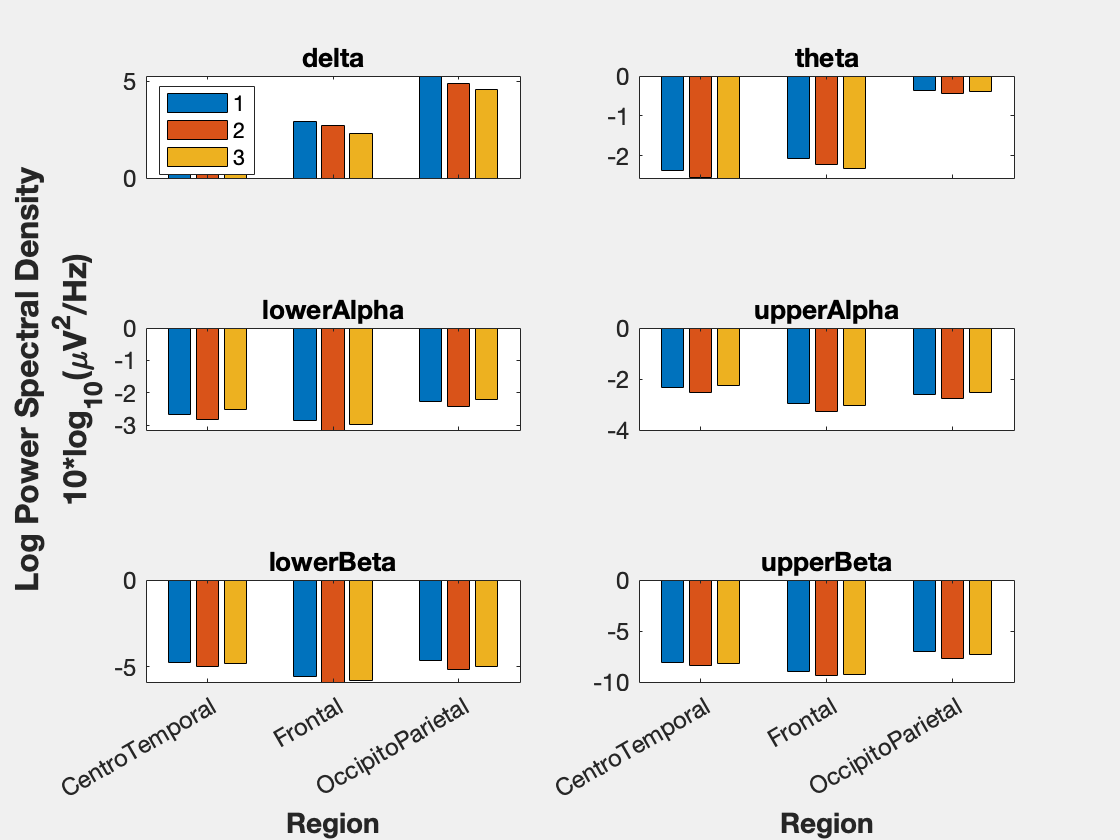

%makeBarPlotByClust(stackedClustStatMean,channel_cluster_names,bands,corrected_p_value_band_chclust_reg,timewindow)
makeBarPlotByBand(stackedClustStatMean,channel_cluster_names,bands,corrected_p_value_band_chclust_reg,timewindow)

#### Bar plots

To better compare, we will try grouped bar plots. Each brain region gets its own plot. Then each band gets clustered together, with the nback values next to each other. This will make it easier to compare the conditions for each n-back.

function makeBarPlotByClust(stackedClustStatMean,channel_cluster_names,bands,corrected_p_value_band_chclust_reg,timewindow)
    % group average
    sigcorp = corrected_p_value_band_chclust_reg < 0.05;
    numsig = sum(sum(sigcorp));
    numSubj = length(unique(stackedClustStatMean.id));
    CI95 = tinv([0.025 0.975], numSubj-1);
    % We have to force this figure to pop out because the error bars won't be
    % dashed otherwise.
    figure; set(gcf,'Visible','on') 
    i = 1;
        
    for cl = 1:length(channel_cluster_names)
            subdata = stackedClustStatMean(stackedClustStatMean.chcluster==channel_cluster_names(cl) & stackedClustStatMean.time_window==timewindow,:);
            legendtext = [];
            subplot(1,length(channel_cluster_names),cl)
            
           
            sumstatsub = grpstats(subdata,["numback","band"],["mean","sem"],"DataVars","mean_mean_10log10","VarNames",["numBack","band","GroupCount","mean","sem"]);
            unsumstatsub_mean = unstack(sumstatsub(:,[1,2,4]),"mean","numBack");
            unsumstatsub_sem = unstack(sumstatsub(:,[1,2,5]),"sem","numBack");

            bar(unsumstatsub_mean{:,2:end})
        
            % eb = errorbar(sumstatsub.numBack,sumstatsub.mean,CI95(2).*sumstatsub.sem,'LineStyle',lineStyle,'LineWidth',2);
            % if ~sigcorp(b,cl) % if sig, make plot
            % 
            %     eb.Bar.LineStyle = 'dotted';
            % end
            % 
            hold on;
                          
        legend(["1","2","3"]);
        fontsize(gca,12,'points')
        title(channel_cluster_names(cl));
    
        if i ==1
            ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
        end
        if i == 2 | i==3
            xlabel("Number Back",'FontSize',14,"FontWeight","bold");
        end
        i = i+1;
    
        hold off;
    end
end


To better compare, we will try grouped bar plots. Each band gets its own plot (which makes things line up better than each region). Then each region gets clustered together, with the nback values next to each other. This will make it easier to compare the conditions for each n-back.

function makeBarPlotByBand(stackedClustStatMean,channel_cluster_names,bands,corrected_p_value_band_chclust_reg,timewindow)
    % group average
    sigcorp = corrected_p_value_band_chclust_reg < 0.05;
    numsig = sum(sum(sigcorp));
    numSubj = length(unique(stackedClustStatMean.id));
    CI95 = tinv([0.025 0.975], numSubj-1);
    % We have to force this figure to pop out because the error bars won't be
    % dashed otherwise.
    figure; set(gcf,'Visible','on') 
    i = 1;
        
    for b = 1:length(bands)
            subdata = stackedClustStatMean(stackedClustStatMean.band==bands(b) & stackedClustStatMean.time_window==timewindow,:);
            legendtext = [];
            subplot(3,length(bands)/3,b)
            
           
            sumstatsub = grpstats(subdata,["numback","chcluster"],["mean","sem"],"DataVars","mean_mean_10log10","VarNames",["numBack","chcluster","GroupCount","mean","sem"]);
            unsumstatsub_mean = unstack(sumstatsub(:,[1,2,4]),"mean","numBack");
            unsumstatsub_sem = unstack(sumstatsub(:,[1,2,5]),"sem","numBack");

            bar(unsumstatsub_mean{:,2:end})
        
            % eb = errorbar(sumstatsub.numBack,sumstatsub.mean,CI95(2).*sumstatsub.sem,'LineStyle',lineStyle,'LineWidth',2);
            % if ~sigcorp(b,cl) % if sig, make plot
            % 
            %     eb.Bar.LineStyle = 'dotted';
            % end
            % 
            hold on;
                          
        fontsize(gca,12,'points')
        title(bands(b));
        xticklabels("")
        if i ==1
            %ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
            legend(["1","2","3"],"Location","northwest");
        elseif i==3 %|| i == 5
            ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
        end
        if i == 5 | i==6
            xticklabels(channel_cluster_names)
            xlabel("Region",'FontSize',14,"FontWeight","bold");
        end
        i = i+1;
    
        hold off;
    end
end

NOT DONE YET.

Plot the individual subjects for the only significant conditions.

sigcorp = corrected_p_value_band_chclust_reg < 0.05;
numsig = sum(sum(sigcorp));
figure;
i=1;
for b = 1:length(bands)
    for cl = 1:length(channel_cluster_names)
        if sigcorp(b,cl) % if sig, make plot
            subdata = stackedClustStatMean(stackedClustStatMean.band==bands{b} & stackedClustStatMean.chcluster==channel_cluster_names(cl) & stackedClustStatMean.time_window==timewindow,:);

            subplot(1,numsig,i)
            tempSubjs = unique(subdata.id);
            for s = 1:length(tempSubjs)
                plot(subdata(subdata.id==string(tempSubjs{s}),:).numback,subdata(subdata.id==string(tempSubjs{s}),:).mean_mean_10log10,'LineWidth',1)
                hold on;
            end
            title(strcat(bands{b},' - ',string(channel_cluster_names(cl))));
            
            sumstatsub = grpstats(subdata,"numback",["mean","sem"],"DataVars","mean_mean_10log10","VarNames",["numback","GroupCount","mean","sem"]);

            errorbar(sumstatsub.numback,sumstatsub.mean,CI95(2).*sumstatsub.sem,'k','LineWidth',2);
            i = i + 1;
        end
    end
end

### Repeated measures ANOVA for comparison of loads

For this comparison, we will look in each frequency band separately (since we know they will have different values). We'll do a repeated measures ANOVA to compare the nback conditions and the region. If there is a main effect or interaction of region, then we will do post-hoc tests to see if 

Repeated measures ANOVAs expect the data to be in a wide format instead of long, so we will reshape it here.

THIS TAKES THE AVERAGE FOR EACH PERSON. WE MIGHT WANT TO RUN THE STATS WHERE THIS TAKES EACH TRIAL FOR EACH PERSON.

temp_data = stackedClustStatMean(ismember(stackedClustStatMean.band,categorical(bands)) & stackedClustStatMean.time_window==timewindow,:);
% turn  from long to wide data
wide_EEG_clust = unstack(temp_data(:,["id","band","numback","chcluster","mean_mean_10log10"]),"mean_mean_10log10","numback");

wide_EEG_clust = unstack(wide_EEG_clust,["x1","x2","x3"],"chcluster")

wide_EEG_clust = 132×11 table
                                               id          band       x1_CentroTemporal    x1_Frontal    x1_OccipitoParietal    x2_CentroTemporal    x2_Frontal    x2_OccipitoParietal    x3_CentroTemporal    x3_Frontal    x3_OccipitoParietal
                                             _______    __________    _________________    __________    ___________________    _________________    __________    ___________________    _________________    __________    ___________________

    CentroTemporal_blank_1_A02_delta         {'A02'}    delta               6.1659            6.

wide_EEG_clust = unstack(wide_EEG_clust,wide_EEG_clust.Properties.VariableNames(3:end),"band")

wide_EEG_clust = 22×55 table
                                          id       x1_CentroTemporal_delta    x1_CentroTemporal_lowerAlpha    x1_CentroTemporal_lowerBeta    x1_CentroTemporal_theta    x1_CentroTemporal_upperAlpha    x1_CentroTemporal_upperBeta    x1_Frontal_delta    x1_Frontal_lowerAlpha    x1_Frontal_lowerBeta    x1_Frontal_theta    x1_Frontal_upperAlpha    x1_Frontal_upperBeta    x1_OccipitoParietal_delta    x1_OccipitoParietal_lowerAlpha    x1_OccipitoParietal_lowerBeta    x1_OccipitoParietal_theta    x1_OccipitoParietal_upperAlpha    x1_OccipitoParietal_upperBeta    x2_CentroTemporal_delta    x2_CentroTemporal_lowerAlpha

The repeated measures ANOVA requies a design matrix that shows the repeated variables. This is visualized below so we can confirm that our model is correct.

withinDesign = table([ones(1,length(bands).*length(channel_cluster_names))  2.*ones(1,length(bands).*length(channel_cluster_names)) 3.*ones(1,length(bands).*length(channel_cluster_names))]',...
    [repmat([ones(1,length(bands)) 2.*ones(1,length(bands)) 3.*ones(1,length(bands))],1,3)]',...
    [repmat(1:length(bands),1,3.*length(channel_cluster_names))]',...
    'VariableNames',{'Load','Region','Band'});

% Plot the model
figure; imagesc(double(withinDesign{:,:})); set(gca,'defaultTextInterpreter','none','TickLabelInterpreter','none');
xticks(1:length(withinDesign.Properties.VariableNames));xticklabels(withinDesign.Properties.VariableNames); yticks(1:height(withinDesign));yticklabels(wide_EEG_clust.Properties.VariableNames(end-height(withinDesign)+1:end));
withinDesign.Load = categorical(withinDesign.Load);
withinDesign.Region = categorical(withinDesign.Region);
withinDesign.Band = categorical(withinDesign.Band);
withinDesign.RegionXBand = withinDesign.Region .* withinDesign.Band; % Create an intersection factor to use for post-hoc testing


After confirming that the model is correct, run the model that includes load, band, and region.

rm_load_region_band = fitrm(wide_EEG_clust,strcat(wide_EEG_clust.Properties.VariableNames{2},'-',wide_EEG_clust.Properties.VariableNames{end},'~ 1'),'WithinDesign',withinDesign);
AT_rm_load_region_band = ranova(rm_load_region_band,'WithinModel','Load*Region*Band')

AT_rm_load_region_band = 16×8 table
                                     SumSq     DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                    _______    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                      9825.6      1      9825.6    103.17    1.4734e-09    1.4734e-09    1.4734e-09    1.4734e-09
    Error                              2000     21      95.239                                                                  
    (Intercept):Load                 15.784      2      7.8921    1.6709       0.20034       0.20394       0.20154       0.2

We observe a trending 3-way interaction between load, region, and band, and an interaction between region and band. Therefore, we must look at each comparison separately, focusing on the question we are interested in, which is: within each region and band, are there differences in the signal based on the load (or number back)?

rm_multcomp_load_region_band = multcompare(rm_load_region_band,'Load','By','RegionXBand'); 

This results in a table that shows the comparison in both directions, which is redundant, so make a smaller version of the table that doesn't compare 1 to 2 and then also 2 to 1. We do this by only keeping the lines of the table where Load_2 is bigger than Load 1.

idx_load2greaterthanload1 = (double(rm_multcomp_load_region_band.Load_2) > double(rm_multcomp_load_region_band.Load_1));
half_rm_multcomp_load_region_band = rm_multcomp_load_region_band(idx_load2greaterthanload1==1,:); 

% The model sorts things alphabetically, so we need to do that here to
% match the region and band orders
alphabeticalbands = sort(bands)

alphabeticalbands = 1×6 string array
    "delta"    "lowerAlpha"    "lowerBeta"    "theta"    "upperAlpha"    "upperBeta"


% We don't have to do this for the regions because they are already
% alphabetical

% Add labels to make the table easier to understand
%tempNames = wide_EEG_clust.Properties.VariableNames(2:1+height(half_rm_multcomp_load_region_band))';


%tempNames = split(tempNames,"_");
%half_rm_multcomp_load_region_band.Band= categorical(tempNames(:,3)); 
%half_rm_multcomp_load_region_band.Region= categorical(tempNames(:,2));
%half_rm_multcomp_load_region_band = sortrows(half_rm_multcomp_load_region_band, "Band", "descend");

% Add effect size measurement for each test and add labels 
effectSize = zeros(height(half_rm_multcomp_load_region_band),1);
for h = 1:height(half_rm_multcomp_load_region_band)  
    % Find the correct band and region based on the numeric labels
    temp_regionxband = char(half_rm_multcomp_load_region_band.RegionXBand(h));
    idx_band = str2double(temp_regionxband(3)); % only works if both are single digits
    tempBand = alphabeticalbands(idx_band);
    idx_region = str2double(temp_regionxband(1));
    tempRegion = channel_cluster_names(idx_region);
    half_rm_multcomp_load_region_band.Band(h) = tempBand;
    half_rm_multcomp_load_region_band.Region(h) = tempRegion;
    %tempBand = string(half_rm_multcomp_load_region_band.Band(h));
    %tempRegion = string(half_rm_multcomp_load_region_band.Region(h));
    higherLoadVal = half_rm_multcomp_load_region_band.Load_2(h);
    lowerLoadVal = half_rm_multcomp_load_region_band.Load_1(h);
    eval(strcat("highValues = wide_EEG_clust.x",string(higherLoadVal),"_",string(tempRegion),"_",string(tempBand),";"))
    eval(strcat("lowValues = wide_EEG_clust.x",string(lowerLoadVal),"_",string(tempRegion),"_",string(tempBand),";"))
    eS  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05);
    effectSize(h) = eS.Effect;

end
half_rm_multcomp_load_region_band.EffectSize = effectSize;
half_rm_multcomp_load_region_band.Band = categorical(half_rm_multcomp_load_region_band.Band);

Show results table

half_rm_multcomp_load_region_band

half_rm_multcomp_load_region_band = 54×11 table
    RegionXBand    Load_1    Load_2    Difference    StdErr     pValue      Lower       Upper        Band           Region        EffectSize
    ___________    ______    ______    __________    _______    _______    ________    _______    __________    ______________    __________

        1 1          1         2         0.25207     0.20513     0.4499    -0.26497     0.7691    delta         CentroTemporal      -0.11422
        1 1          1         3         0.69012     0.37979    0.18842    -0.26718     1.6474    delta         CentroTemporal      -0.34153
        1 1  

Show just significant results

half_rm_multcomp_load_region_band(half_rm_multcomp_load_region_band.pValue<0.05,:)

ans = 3×11 table
    RegionXBand    Load_1    Load_2    Difference    StdErr      pValue        Lower       Upper       Band            Region         EffectSize
    ___________    ______    ______    __________    _______    _________    _________    _______    _________    ________________    __________

        2 6          1         2        0.39754      0.15594      0.04713    0.0044772    0.79061    upperBeta    Frontal               -0.2322 
        3 3          1         2        0.48906       0.1416    0.0064419      0.13215    0.84598    lowerBeta    OccipitoParietal     -0.32189 
        3 6          1      

comp2 = half_rm_multcomp_load_region_band(double(half_rm_multcomp_load_region_band.Load_1)==2,:)
% Only make for comparison of 2 and 3, as these are the only sig.
pvalmap = unstack(half_rm_multcomp_load_region_band(double(half_rm_multcomp_load_region_band.Load_1)==2,["Band","Region","pValue"]),"pValue","Region");
pvalmap = pvalmap([6 3 5 2 4 1],:);

figure;
imagesc(pvalmap{:,2:4}); clim([0 0.05]); colorbar; colormap('pink');
xticks(1:length(channel_cluster_names)); xticklabels(pvalmap.Properties.VariableNames(2:end));
yticks(1:length(pvalmap.Band)); yticklabels(pvalmap.Band);
title('P-values for post-hoc low vs high');

This is code to do an ANOVA for each band separately. It may be that because of the 3 way interaction above that we just do multicompare for every pair, so ignore this. We do expect the bands to have different values, so it might make sense to separate them, but multcomp above also does this.

Repeated measures ANOVAs expect the data to be in a wide format instead of long, so we will reshape it here.

% for c = 1:length(conds) % only want to do blank
%     timewindow = conds(c)
%     for b = 1:length(bands)
%         bands(b)
%         % filter by band and condition
%         temp_data = stackedClustStat(stackedClustStat.band==bands{b} & stackedClustStat.time_window==timewindow,:);
%         % turn  from long to wide data
%         wide_EEG_clust = unstack(temp_data(:,["id","numback","chcluster","mean_10log10"]),"mean_10log10","numback");
%         wide_EEG_clust = unstack(wide_EEG_clust,["x1","x2","x3"],"chcluster")

The repeated measures ANOVA requies a design matrix that shows the repeated variables. This is visualized below so we can confirm that our model is correct.

%         withinDesign = table([ones(1,length(channel_cluster_names))  2.*ones(1,length(channel_cluster_names)) 3.*ones(1,length(channel_cluster_names))]',...
%             [repmat([1 2 3],1,3)]',...
%             'VariableNames',{'Load','Region'});
% 
%         % Plot the model
%         figure; imagesc(double(withinDesign{:,:})); set(gca,'defaultTextInterpreter','none','TickLabelInterpreter','none');
%         xticks(1:length(withinDesign.Properties.VariableNames));xticklabels(withinDesign.Properties.VariableNames); yticks(1:height(withinDesign));yticklabels(wide_EEG_clust.Properties.VariableNames(end-height(withinDesign)+1:end));
%         withinDesign.Load = categorical(withinDesign.Load);
%         withinDesign.Region = categorical(withinDesign.Region);
%         withinDesign.RegionXLoad = withinDesign.Region .* withinDesign.Load; % Create an intersection factor to use for post-hoc testing
% 

After confirming that the model is correct, run the model that includes load and region.

%         rm_load_region_band = fitrm(wide_EEG_clust,strcat(wide_EEG_clust.Properties.VariableNames{2},'-',wide_EEG_clust.Properties.VariableNames{end},'~ 1'),'WithinDesign',withinDesign);
%         AT_rm_load_region_band = ranova(rm_load_region_band,'WithinModel','Load*Region')
%         rm_multcomp_load_region_band = multcompare(rm_load_region_band,'Load','By','RegionXLoad'); 
%     end
% end

## Helper Functions

### Calculate absolute power from the spectra for frequency bands of interest. 

function [absolutePower] = getAbsolutePower(spectra,freqs,freqBands)
% Put in a 2d spectra (ch x freqs), get out 2d matrix of ch x bandpowers
    absolutePower = zeros(size(spectra,1),height(freqBands));
    for b = 1:height(freqBands)
        % find the index of the frequencies between those values
        % (non-inclusive)
        freqIdx = find(freqs >= freqBands.LowFreq(b) & freqs<=freqBands.HighFreq(b)); % changed to include equal to because bands are on the ints
        if isempty(freqIdx)
            !warning("No frequencies fall within the range, make band larger. It is inclusive.")
        end
        % Convert spectra to mean absolute power 
        if size(size(spectra),2) == 2
            absolutePower(:,b) = mean(10.^(spectra(:,freqIdx)/10),2);
        elseif size(size(spectra),2) == 3

        else
            !warning("Too many dimensions bro")
        end
    end
end


This takes in the data with subjects as rows.

function plotAgainstConditionValues(conditionValues,tempData,metricLabel,errorBarType,individualOn)
    if individualOn
        for i = 1:size(tempData,1)
            if i <= 3
                plot(conditionValues,tempData(i,:),'x-','MarkerSize',10);
                hold on;  
            elseif i <=10
                plot(conditionValues,tempData(i,:),'d--','MarkerSize',8);
                hold on;  
            else
                plot(conditionValues,tempData(i,:),'o-.','MarkerSize',10);
                hold on;
            end
                
        end
    end
    errorVals = calculateError(tempData,errorBarType);
    errorbar(conditionValues,mean(tempData),errorVals,'k','LineWidth',2);
    plot(conditionValues,mean(tempData),'k.','MarkerSize',30); 
    hold off;
    fontsize(gca,12,'points')
    xlim([3.75 7.25]); xticks(4:7); xlabel('Number of Letters','FontSize',16,"FontWeight","bold");
    ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

end
function [errorValues ] = calculateError(dataSubjsAsRows,errorType)
    numSubj = size(dataSubjsAsRows,1);    
    switch errorType
        case 'std'
            errorValues = std(dataSubjsAsRows);
        case 'sem'
            errorValues = std(dataSubjsAsRows)./sqrt(numSubj);
        case '95sem'
            CI95 = tinv([0.025 0.975], numSubj-1);
            errorValues = CI95(2).*(std(dataSubjsAsRows)./sqrt(numSubj));
        otherwise
            warning('errorType does not match any options, returning zeros')
            errorValues = zeros(1,size(dataSubjsAsRows,2));
    end  
end

function [outtable] = putLMEresultsTable(lmemodel,sourceType)

    [~,~,stats] = covarianceParameters(lmemodel);
    if sourceType == "EEG"
        outtable = table(lmemodel.Variables.band(1),...
            lmemodel.Variables.chcluster(1),... 
            lmemodel.Coefficients(2,:).Estimate,...
            lmemodel.Coefficients(2,:).SE,...
            lmemodel.Coefficients(2,:).tStat,...
            lmemodel.Coefficients(2,:).pValue,...
            lmemodel.Coefficients(2,:).Lower,...
            lmemodel.Coefficients(2,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'chcluster','Band','Estimate','SE','tStat','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});
    else
        loadValIdx = find(strcmp(lmemodel.CoefficientNames,'LoadVal'));
        outtable = table(sourceType,... 
            lmemodel.Coefficients(loadValIdx,:).Estimate,...
            lmemodel.Coefficients(loadValIdx,:).SE,...
            lmemodel.Coefficients(loadValIdx,:).tStat,...
            lmemodel.Coefficients(loadValIdx,:).DF,...
            lmemodel.Coefficients(loadValIdx,:).pValue,...
            lmemodel.Coefficients(loadValIdx,:).Lower,...
            lmemodel.Coefficients(loadValIdx,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'Measurement','Estimate','SE','tStat','df','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});

    end
end